Load data

clear all

% Parameters to test for wavelets
ParamsToCheck.TimeBandWidth = [5,10,15,20,30,40,80,100];

% Parameters to test for peak trough
ParamsToCheck.StdLimsHigh = [0.5,0.4,0.3,0.2,0.15]; % Std for first round of peak detection
ParamsToCheck.StdLimsLow = [0.15,0.1,0.05,0.01]; % Std for second round of peak detection

% Parameters to keep : Options for WV and Options1 for Peak/Trough
Options.Fs = 1250; % sampling rate of LFP
Options.FilBand = [1 20]; % band to filter LFP
Options.NumOctaves = 6; % WV param, defiens min adn max frequency
Options.VoicesPerOctave = 48; % WV param defines sampling of frequency bands
Options.FreqLim = [1.5,15]; % After calculate WV is restricted to these bands to get peak
Options.WVDownsample = 10; % LFP is downsamples before calculation
Options1 = Options;
Options1.Fs = Options.Fs/Options.WVDownsample;
Options1.TimeLim=0.05; % in second, minimum distance between two minima or


ChannelTypes = {'Bulb','HPC_deep','HPC_sup'};
SessNames = {'SleepPreUMaze','UMazeCond'};


%% Look at results
ChannelTypes = {'Bulb','HPC_deep','HPC_sup'};
SessNames = {'SleepPreUMaze','UMazeCond'};
MiceList = [507,508,509];

for ss=1;%:length(SessNames)
    Dir = PathForExperimentsEmbReact(SessNames{ss});
    for dd=1:length(Dir.path)
        if ismember(Dir.ExpeInfo{dd}{1}.nmouse,MiceList)
            for ddd=1:length(Dir.path{dd})
                cd(Dir.path{dd}{ddd})
                disp(Dir.path{dd}{ddd})
                load('CalcPhaseParameterSearch.mat')
                for chan=1:length(ChannelTypes)
                    
                    AllWV_Error.(ChannelTypes{chan})(find(MiceList==Dir.ExpeInfo{dd}{1}.nmouse),:) = WV_Error.(ChannelTypes{chan});
                    AllPT_Error.(ChannelTypes{chan})(find(MiceList==Dir.ExpeInfo{dd}{1}.nmouse),:,:) = PT_Error.(ChannelTypes{chan});
                    AllPTvsWV_Error_TB.(ChannelTypes{chan})(find(MiceList==Dir.ExpeInfo{dd}{1}.nmouse),:) = squeeze(WVvsPT_Error.(ChannelTypes{chan})(4,3,:));
                    AllPTvsWV_ErrorBis_Hi.(ChannelTypes{chan})(find(MiceList==Dir.ExpeInfo{dd}{1}.nmouse),:) = squeeze(WVvsPT_Error.(ChannelTypes{chan})(:,3,3));
                    AllPTvsWV_ErrorBis_Lo.(ChannelTypes{chan})(find(MiceList==Dir.ExpeInfo{dd}{1}.nmouse),:) = squeeze(WVvsPT_Error.(ChannelTypes{chan})(4,:,3));

                end
            end
        end
    end
end

/media/DataMOBsRAIDN/ProjectEmbReact/Mouse507/20170201/ProjectEmbReact_M507_20170201_SleepPre/
/media/DataMOBsRAIDN/ProjectEmbReact/Mouse508/20170203/ProjectEmbReact_M508_20170203_SleepPre/
/media/DataMOBsRAIDN/ProjectEmbReact/Mouse509/20170204/ProjectEmbReact_M509_20170204_SleepPre/


First look at the error relative to the signal

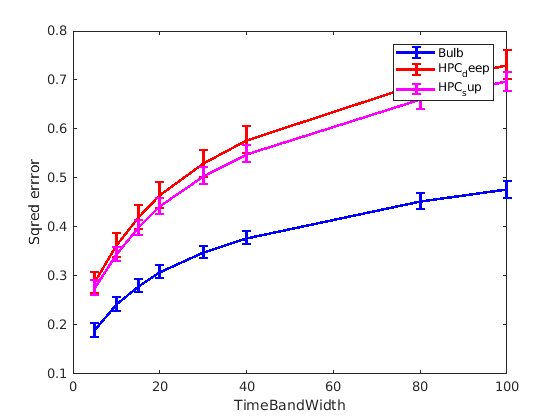


figure
Chan_Cols={'b','r','m'};
for chan=1:length(ChannelTypes)
    errorbar(ParamsToCheck.TimeBandWidth,mean(AllWV_Error.(ChannelTypes{chan})),stdError(AllWV_Error.(ChannelTypes{chan})),'color',Chan_Cols{chan},'linewidth',2), hold on
end
xlabel('TimeBandWidth')
ylabel('Sqred errror')
legend(ChannelTypes)

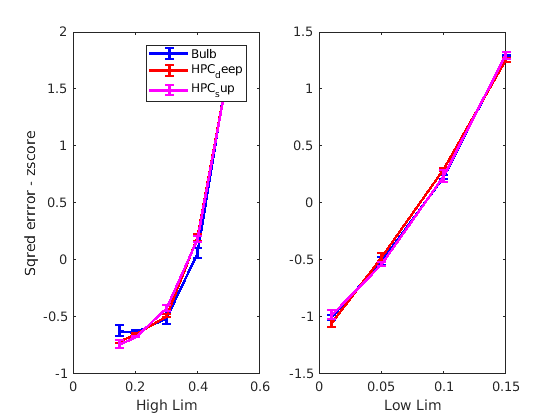


figure
subplot(121)
for chan=1:length(ChannelTypes)
    PT_averaged_High=zscore(squeeze([mean(AllPT_Error.(ChannelTypes{chan}),3)])')';
    errorbar(ParamsToCheck.StdLimsHigh,mean(PT_averaged_High),stdError(PT_averaged_High),'color',Chan_Cols{chan},'linewidth',2), hold on
end
xlabel('High Lim')
ylabel('Sqred errror - zscore')
legend(ChannelTypes)

subplot(122)
for chan=1:length(ChannelTypes)
    PT_averaged_Low=zscore(squeeze([mean(AllPT_Error.(ChannelTypes{chan}),2)])')';
    errorbar(ParamsToCheck.StdLimsLow,mean(PT_averaged_Low),stdError(PT_averaged_Low),'color',Chan_Cols{chan},'linewidth',2), hold on
end
xlabel('Low Lim')

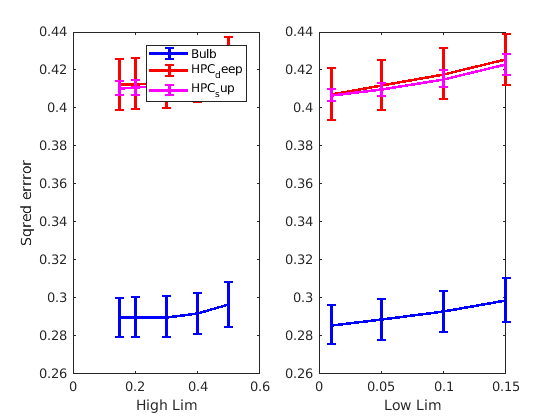


figure
subplot(121)
for chan=1:length(ChannelTypes)
    PT_averaged_High=(squeeze([mean(AllPT_Error.(ChannelTypes{chan}),3)])')';
    errorbar(ParamsToCheck.StdLimsHigh,mean(PT_averaged_High),stdError(PT_averaged_High),'color',Chan_Cols{chan},'linewidth',2), hold on
end
xlabel('High Lim')
ylabel('Sqred errror')
legend(ChannelTypes)
subplot(122)
for chan=1:length(ChannelTypes)
    PT_averaged_Low=(squeeze([mean(AllPT_Error.(ChannelTypes{chan}),2)])')';
    errorbar(ParamsToCheck.StdLimsLow,mean(PT_averaged_Low),stdError(PT_averaged_Low),'color',Chan_Cols{chan},'linewidth',2), hold on
end
xlabel('Low Lim')

Look at error of one signal compared to another

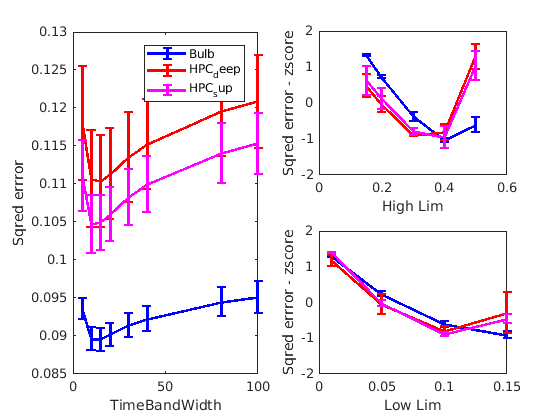


figure
subplot(121)
for chan=1:length(ChannelTypes)
    errorbar(ParamsToCheck.TimeBandWidth,mean(AllPTvsWV_Error_TB.(ChannelTypes{chan})),stdError(AllPTvsWV_Error_TB.(ChannelTypes{chan})),'color',Chan_Cols{chan},'linewidth',2), hold on
end
xlabel('TimeBandWidth')
ylabel('Sqred errror')
legend(ChannelTypes)
subplot(222)
for chan=1:length(ChannelTypes)
    errorbar(ParamsToCheck.StdLimsHigh,mean(zscore(AllPTvsWV_ErrorBis_Hi.(ChannelTypes{chan})')'),stdError(zscore(AllPTvsWV_ErrorBis_Hi.(ChannelTypes{chan})')'),'color',Chan_Cols{chan},'linewidth',2), hold on
end
xlabel('High Lim')
ylabel('Sqred errror - zscore')
subplot(224)
for chan=1:length(ChannelTypes)
    errorbar(ParamsToCheck.StdLimsLow,mean(zscore(AllPTvsWV_ErrorBis_Lo.(ChannelTypes{chan})')'),stdError(zscore(AllPTvsWV_ErrorBis_Lo.(ChannelTypes{chan})')'),'color',Chan_Cols{chan},'linewidth',2), hold on
end
xlabel('Low Lim')
ylabel('Sqred errror - zscore')